%Pretty condition
u = 30;
v = 10;
D = 2;

t_start = 0;
t_final = 0.1;
dt = 0.001;
n_step_time = (t_final-t_start)/dt;

x_start = 0;
x_final = 10;
dx = 0.1;
n_step_space_x = (x_final - x_start)/dx;

y_start = 0;
y_final = 10;
dy = 0.1;
n_step_space_y = (y_final - y_start)/dy;

x = linspace(x_start, x_final, n_step_space_x);
y = linspace(y_start, y_final, n_step_space_y);
t = linspace(t_start, t_final, n_step_time);

alpha_x = u*dt/(2*dx);
alpha_y = v*dt/(2*dy);
beta_x = D*dt/(dx^2);
beta_y = D*dt/(dy^2);

if (4*(alpha_x^2) < 2*beta_x && 2*beta_x < 1)
   disp("Stability respected for x!")
else
    disp("Stability not respected for x!")
end

if (4*(alpha_y^2) < 2*beta_y && 2*beta_y < 1)
   disp("Stability respected for y!")
else
    disp("Stability not respected for y!")
end



% Condizioni di Dirichlet
% Sono gia rispettate perche la matrice è di tutti 0
T = zeros(n_step_space_x, n_step_space_y,n_step_time);

for i = 2:n_step_space_x-1
    for j = 2: n_step_space_y-1 
        T(i, j, 1) = exp(-(dx*(i-(n_step_space_x)/2))^2)* ...
        exp(-(dy*(j-(n_step_space_y)/2))^2);
    end
end



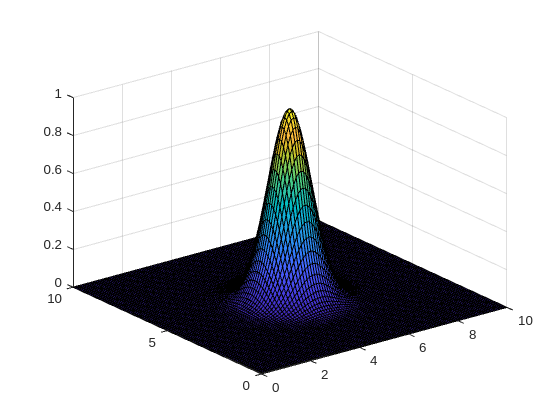

surf(x,y,T(:,:,1))

% i indice per le x
% j indice per le y
% k indice per le t
for k = 2:n_step_time
    for i = 2:n_step_space_x-1
        for j = 2:n_step_space_y-1

        A_x = alpha_x*(T(i+1,j, k-1) - T(i-1,j, k-1));
        B_x = beta_x*( T(i+1, j, k-1) - 2*T(i, j, k-1) + ...
            T(i-1, j, k-1) );

        A_y = alpha_y*(T(i,j+1, k-1) - T(i,j-1, k-1));
        B_y = beta_y*( T(i, j+1, k-1) - 2*T(i, j, k-1) + ...
            T(i, j-1, k-1) );

        T(i,j, k) = T(i, j, k-1) - A_x - A_y + B_x + B_y;

        end
    end
end

tempo = 10;
point = [0,0];
val = max(max(T(:,:,tempo)));

for i = 1:n_step_space_x
    for j = 1:n_step_space_y
        if (T(i,j,tempo) == val)
            point = [i,j];
        end
    end
end

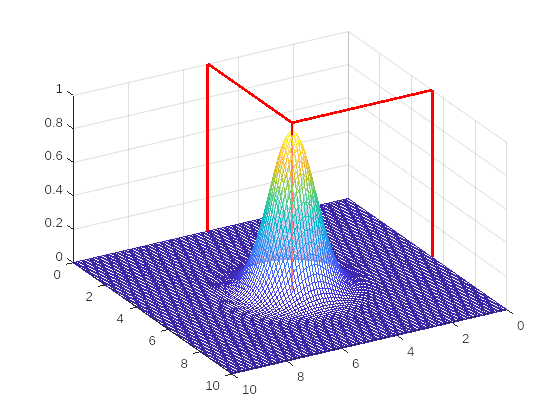

clf;
values = linspace(0,1,100);
xx = dx*point(1)*ones(1, n_step_space_x);
yy = dy*point(2)*ones(1, n_step_space_y);
zz = values;
mesh(x,y,T(:,:,tempo), 'FaceAlpha', 0.5);
hold on;
plot3(yy,xx,values,'Color','red','LineWidth',2);
plot3(zeros(n_step_space_x),xx,values,'Color','red','LineWidth',2);
plot3(yy,linspace(0,point(1)*dx,100),ones(1, n_step_space_y),'Color','red','LineWidth',2);

plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(linspace(0,point(2)*dx,100),xx,ones(1, n_step_space_y),'Color','red','LineWidth',2);

shading interp;
view(150, 37.5);
hold off;

tempo = 30;
point = [0,0];
val = max(max(T(:,:,tempo)));

for i = 1:n_step_space_x
    for j = 1:n_step_space_y
        if (T(i,j,tempo) == val)
            point = [i,j];
        end
    end
end

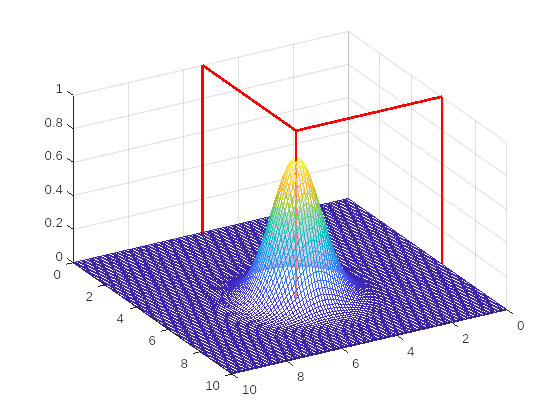

clf;
values = linspace(0,1,100);
xx = dx*point(1)*ones(1, n_step_space_x);
yy = dy*point(2)*ones(1, n_step_space_y);
zz = values;
mesh(x,y,T(:,:,tempo), 'FaceAlpha', 0.5);
hold on;
plot3(yy,xx,values,'Color','red','LineWidth',2);
plot3(zeros(n_step_space_x),xx,values,'Color','red','LineWidth',2);
plot3(yy,linspace(0,point(1)*dx,100),ones(1, n_step_space_y),'Color','red','LineWidth',2);

plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(linspace(0,point(2)*dx,100),xx,ones(1, n_step_space_y),'Color','red','LineWidth',2);

shading interp;
view(150, 37.5);
hold off;

tempo = 60;
point = [0,0];
val = max(max(T(:,:,tempo)));

for i = 1:n_step_space_x
    for j = 1:n_step_space_y
        if (T(i,j,tempo) == val)
            point = [i,j];
        end
    end
end

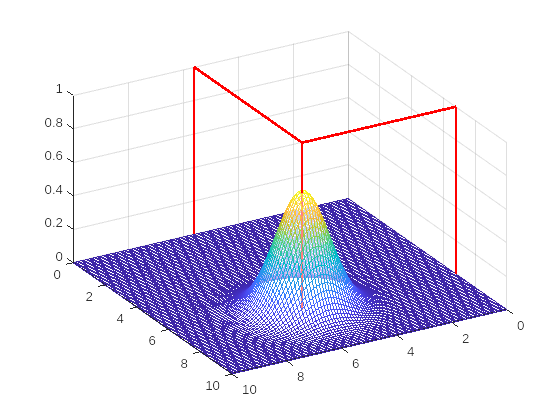

clf;
values = linspace(0,1,100);
xx = dx*point(1)*ones(1, n_step_space_x);
yy = dy*point(2)*ones(1, n_step_space_y);
zz = values;
mesh(x,y,T(:,:,tempo), 'FaceAlpha', 0.5);
hold on;
plot3(yy,xx,values,'Color','red','LineWidth',2);
plot3(zeros(n_step_space_x),xx,values,'Color','red','LineWidth',2);
plot3(yy,linspace(0,point(1)*dx,100),ones(1, n_step_space_y),'Color','red','LineWidth',2);

plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(linspace(0,point(2)*dx,100),xx,ones(1, n_step_space_y),'Color','red','LineWidth',2);

shading interp;
view(150, 37.5);
hold off;

tempo = 80;
point = [0,0];
val = max(max(T(:,:,tempo)));

for i = 1:n_step_space_x
    for j = 1:n_step_space_y
        if (T(i,j,tempo) == val)
            point = [i,j];
        end
    end
end

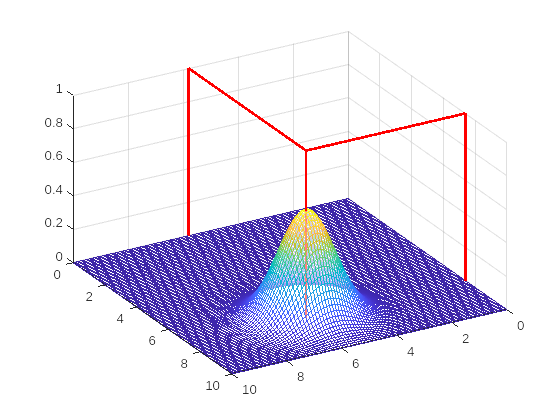

clf;
values = linspace(0,1,100);
xx = dx*point(1)*ones(1, n_step_space_x);
yy = dy*point(2)*ones(1, n_step_space_y);
zz = values;
mesh(x,y,T(:,:,tempo), 'FaceAlpha', 0.5);
hold on;
plot3(yy,xx,values,'Color','red','LineWidth',2);
plot3(zeros(n_step_space_x),xx,values,'Color','red','LineWidth',2);
plot3(yy,linspace(0,point(1)*dx,100),ones(1, n_step_space_y),'Color','red','LineWidth',2);

plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(linspace(0,point(2)*dx,100),xx,ones(1, n_step_space_y),'Color','red','LineWidth',2);

shading interp;
view(150, 37.5);
hold off;

tempo = 100;
point = [0,0];
val = max(max(T(:,:,tempo)));

for i = 1:n_step_space_x
    for j = 1:n_step_space_y
        if (T(i,j,tempo) == val)
            point = [i,j];
        end
    end
end

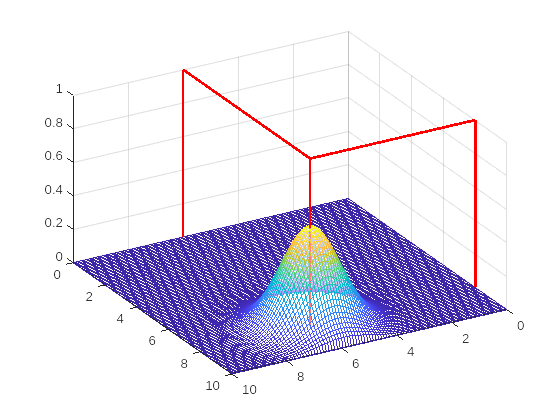

clf;
values = linspace(0,1,100);
xx = dx*point(1)*ones(1, n_step_space_x);
yy = dy*point(2)*ones(1, n_step_space_y);
zz = values;
mesh(x,y,T(:,:,tempo), 'FaceAlpha', 0.5);
hold on;
plot3(yy,xx,values,'Color','red','LineWidth',2);
plot3(zeros(n_step_space_x),xx,values,'Color','red','LineWidth',2);
plot3(yy,linspace(0,point(1)*dx,100),ones(1, n_step_space_y),'Color','red','LineWidth',2);

plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(yy,zeros(n_step_space_y),values,'Color','red','LineWidth',2);
plot3(linspace(0,point(2)*dx,100),xx,ones(1, n_step_space_y),'Color','red','LineWidth',2);

shading interp;
view(150, 37.5);
hold off;

clf